% adding cross section to 3D scatter
% plotting only one dot per cell, the average pole age of the cell
%myfolder = '/MATLAB Drive/myfolder' ;   % new folder name 
%folder = mkdir([filepath,filesep,myfolder]) ;
%filepath  = [filepath,filesep,myfolder];
i_cells =118;
file_path = sprintf('Cells/%d.txt',i_cells);
cells=importdata(file_path);

%x = [cells(:,4);cells(:,7)];
%y = [cells(:,5);cells(:,8)];
%z = [cells(:,6);cells(:,9)];
%c = [cells(:,27);cells(:,28)] %pole ages
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
lengths = cells(:,10);
c1 = cells(:,27); % p age
c2 = cells(:,28); % q age

c = (c1 + c2)/2; % average pole age for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

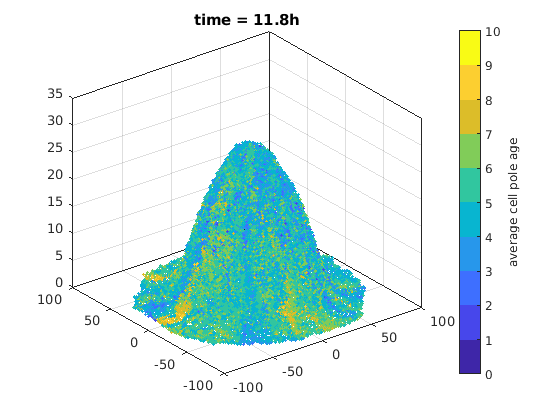


subplot(1,1,1)
scatter3(x,y,z,5,c, 'filled');
axis([-100 100 -100 100 0 35])
box on
h1=colorbar;
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h'])

h1.Label.String = 'average cell pole age';

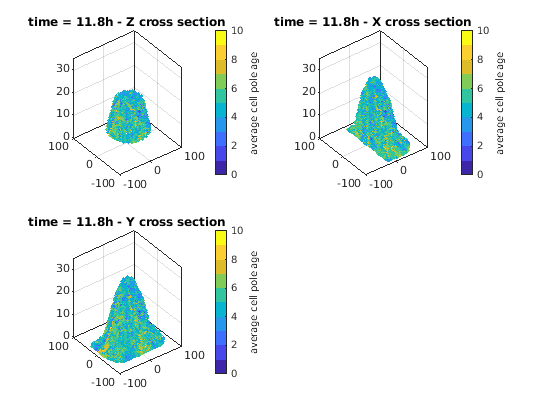


subplot(2,2,1)
z_min =6;
z_max =20;
indices_of_z = find((z<z_max & z>z_min));
scatter3(x(indices_of_z),y(indices_of_z),z(indices_of_z),5,c(indices_of_z), 'filled');
axis([-100 100 -100 100 0 35])
box on
h1=colorbar;
h1.Label.String = 'average cell pole age';
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h - Z cross section'])

subplot(2,2,2)
x_min =-21;
x_max =75;
indices_of_x = find((x<x_max & x>x_min));
scatter3(x(indices_of_x),y(indices_of_x),z(indices_of_x),5,c(indices_of_x), 'filled');
axis([-100 100 -100 100 0 35])
box on
h1=colorbar;
h1.Label.String = 'average cell pole age';
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h - X cross section'])

subplot(2,2,3)
y_min =-68;
y_max =47;
indices_of_y = find((y<y_max & y>y_min));
scatter3(x(indices_of_y),y(indices_of_y),z(indices_of_y),5,c(indices_of_y), 'filled');
axis([-100 100 -100 100 0 35])
%view(90,0);
box on
h1=colorbar;
h1.Label.String = 'average cell pole age';
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h - Y cross section'])

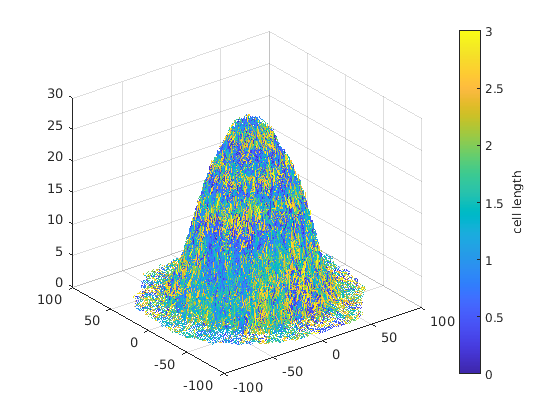

length_plot(x1,y1,z1,x2,y2,z2,lengths)